# Solving Continuous & Hybrid Systems (ODEs) in MATLAB

## Solving Continuous System - Free-Falling Ball

A free-falling ball is a continuous system since the evolution of its state variables vary continuously.

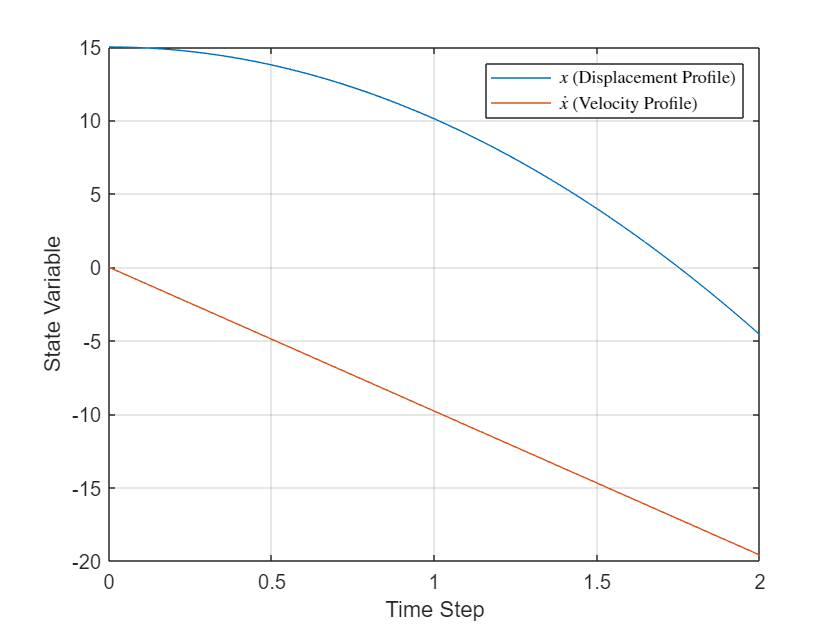

clear all
tspan=linspace(0,2,1001)'; % Time steps (0-2 sec)
y0=[15 0]'; % Initial conditions [pos vel]
[t,y]=ode45(@ball,tspan,y0); % Solve continuous system using ODE45
plot(t,y)
xlabel("Time Step")
ylabel("State Variable")
legend("$x$ (Displacement Profile)", "$\dot{x}$ (Velocity Profile)",'Interpreter','latex')
grid on

## Solving Hybrid System - Bouncing Ball

A bouncing ball is a hybrid system since the evolution of its state variables vary continuously when falling, but have a discrete change (velocity is reversed) when entering in collision with the ground.

### Single Bounce - Stop Integration upon Colliding with Ground

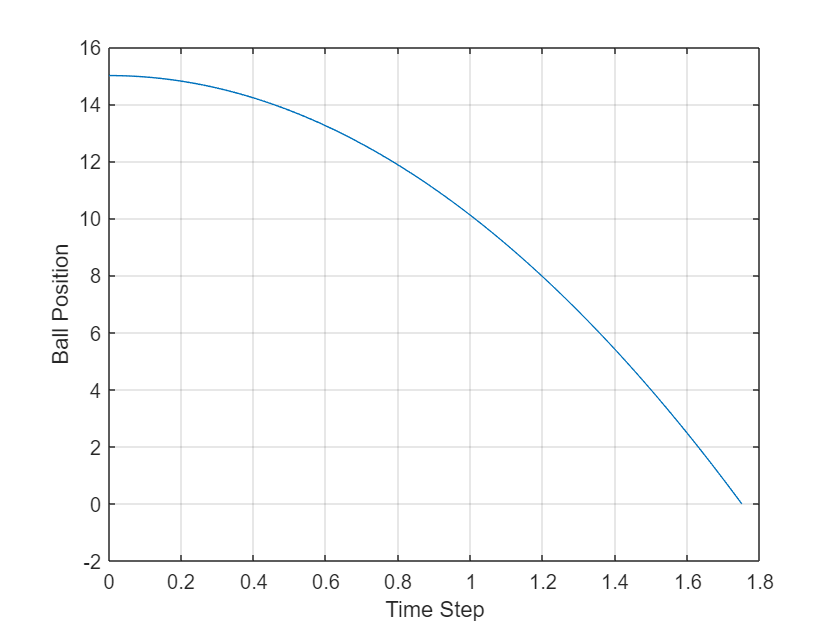

clear all
tspan=linspace(0,2,1001)';
y0=[15 0];
opt = odeset('Events',@events);
[t,y]=ode45(@ball,tspan,y0,opt);
plot(t,y(:,1))
xlabel("Time Step")
ylabel("Ball Position")
grid on

### Multiple Bounces (Perfectly Elastic Collision) - Using a FOR Loop

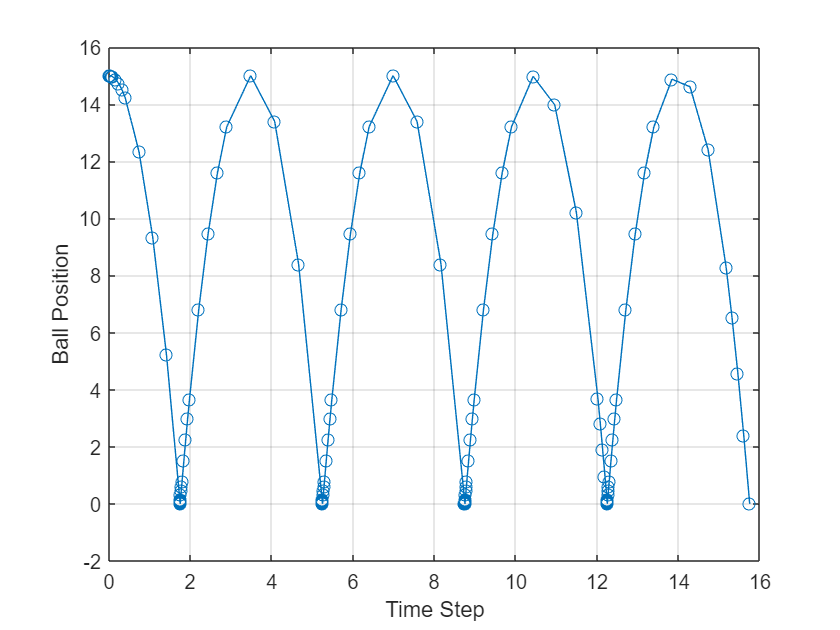

clear all
tstart = 0;
t_cum = tstart;
tfinal = 30; % Also depends on number of bounces whether the simulation will run until `tfinal` steps
y0 = [15 0];
y_cum = y0;
opt = odeset('Events',@events);
for i = 1:5 % 5 bounces (also depends on `tfinal` whether these many number of bounces can be acheived)
[t,y,te,ye,ie]=ode45(@ball,[tstart 
tfinal],y0,opt);
m = length(t);
t_cum = [t_cum;t];
y_cum = [y_cum;y];
tstart = te;
y0 = [0 -y(m,2)];
end
plot(t_cum,y_cum(:,1),'-o')
xlabel("Time Step")
ylabel("Ball Position")
grid on

### Multiple Bounces (Non-Elastic Collision) - Using a FOR Loop

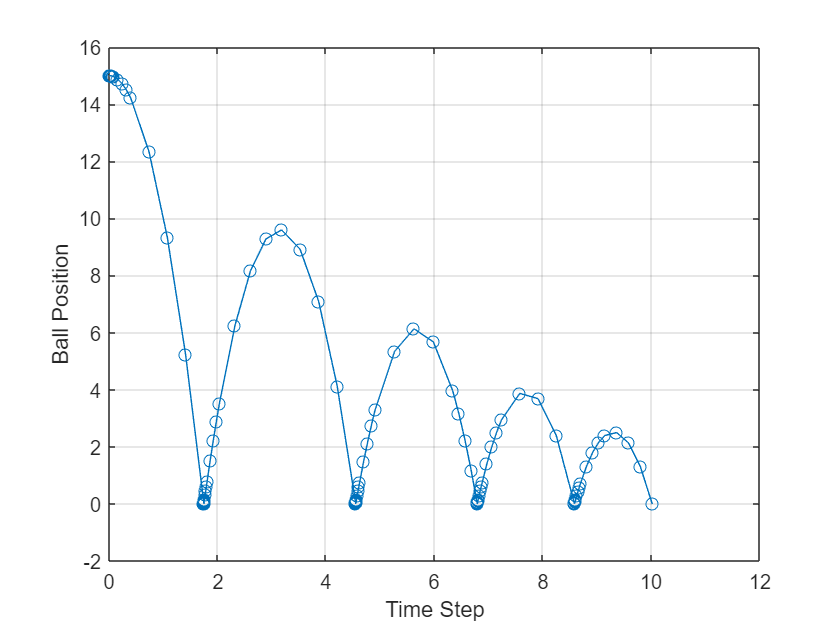

clear all
tstart = 0;
t_cum = tstart;
tfinal = 30; % Also depends on number of bounces whether the simulation will run until `tfinal` steps
y0 = [15 0];
y_cum = y0;
opt = odeset('Events',@events);
for i = 1:5 % 5 bounces (also depends on `tfinal` whether these many number of bounces can be acheived)
[t,y,te,ye,ie]=ode45(@ball,[tstart 
tfinal],y0,opt);
m = length(t);
t_cum = [t_cum;t];
y_cum = [y_cum;y];
tstart = te;
y0 = [0 -0.8*y(m,2)];
end
plot(t_cum,y_cum(:,1),'-o')
xlabel("Time Step")
ylabel("Ball Position")
grid on

function f=ball(t,y) % ODEFUN must have input arguments of time vector and the states
f(1)=y(2); % x1dot = x2
f(2)=-9.8; % x2dot = -9.8
f=[f(1) f(2)]';
end

function [value,isterminal,direction]=events(t,y)
value=y(1);
isterminal=1;
direction=-1;
end